**Дополнительная задача**

**Топольницкий А.**

**Вариант 53**

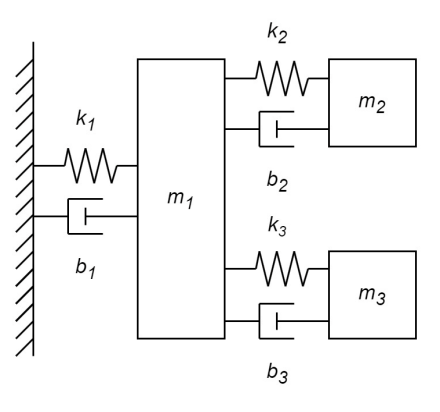

**Аналитическое моделирование**

Функцию Лагранжа для всей системы можно записать в следующем виде:

$$L = L_1 + L_2 = K_1-P_1 + K_2-P_2+K_3-P_3$, где

$$L_1 = \frac{1}{2}m_1\dot{x_1}^2 - (\frac{1}{2}k_1x_1^2 + \frac{1}{2}k_2[x_1-x_2]^2+\frac{1}{2}k_3[x_1-x_3]^2)$$, 

$$L_2 = \frac{1}{2}m_2\dot{x_2}^2 -  \frac{1}{2}k_2[x_1-x_2]^2$$,


$$$L_3 = \frac{1}{2}m_3\dot{x_3}^2 -  \frac{1}{2}k_3[x_1-x_3]^2$$$


Уравнения Эйлера-Лагранжа для механической системы можно записать в виде

$$\frac{d}{dt}\Big(\frac{\partial L}{\partial \dot{x}}\Big) - \frac{\partial L}{\partial {x}}= Q$$, где $Q$ - внешняя сила

$$\frac{d}{dt}\Big(\frac{\partial L_1}{\partial \dot{x}_1}\Big) = m\ddot{x}_1$$,

 $$\frac{\partial L_1}{\partial x_1} =-k_1x_1 - k_2[x_1-x_2]-k_3[x_1-x_3]$$,

 
$$$Q_1 = -b_1 \dot{x}_1 - b_2[\dot{x}_1-\dot{x}_2]-b_3[\dot{x}_1-\dot{x}_3] $$$


$$\frac{d}{dt}\Big(\frac{\partial L_2}{\partial \dot{x}_2}\Big) = m\ddot{x}_2$$, $$\frac{\partial L_2}{\partial x_2} =k_2[x_1-x_2]$$, $$Q_2 =  b_2[\dot{x}_1-\dot{x}_2] $$,

$$\frac{d}{dt}\Big(\frac{\partial L_3}{\partial \dot{x}_3}\Big) = m\ddot{x}_3$$, $$\frac{\partial L_3}{\partial x_3} =k_3[x_1-x_3]$$, $$Q_3 =  b_3[\dot{x}_1-\dot{x}_3] $$,

Тогда итоговую систему можно переписать так


$$$\left\{\begin{array}{@{}ll@{}} m\ddot{x}_1 = -k_1x_1 - k_2[x_1-x_2]-k_3[x_1-x_3]-b_1 \dot{x}_1 - b_2[\dot{x}_1-\dot{x}_2]-b_3[\dot{x}_1-\dot{x}_3]  \\ m\ddot{x}_2 =k_2[x_1-x_2]+b_2[\dot{x}_1-\dot{x}_2] \\ m\ddot{x}_3 =k_3[x_1-x_3]+b_3[\dot{x}_1-\dot{x}_3]  \end{array}\right.$$$


Задание начальных данных:

clc; clear all;
m1 = 3.7; m2 = 12; m3 = 20.8; % kg 
b1 = 25.13851; b2 = 1e-9; b3 = 12.24894; % N/(m/s)
k1 = 228.5319; k2 = 182.9234; k3 = 81.65957; % N/m
x1_0 = -5; x2_0 = -15; x3_0 = 10; % m

F_1 = 0; F_2 = 10; F_3 = 10; % N
time_F_1 = 0.5; time_F_2 = 0.5; time_F_3 = 0.5; % s
t = 35; %s [simulation time]
% all time must be >0 !!!

Запуск модели:

F_r = [F_1, F_2, F_3, 0]; F_1 = 0; F_2 = 0; F_3 = 0;

x1 = [x1_0, x1_0 * 1, x1_0 * 1, 0];
x2 = [x2_0, x2_0 * 1, x2_0 * 1, 0];
x3 = [x3_0, x3_0 * 2, x3_0 * 5, 0];

x1_0 = x1(1); x2_0 = x2(1); x3_0 = x3(1);

simu_1 = sim('extra_simulink.slx',...
    'StartTime','0','StopTime', num2str(t));
sims_1= sim('extra_simscape.slx',...
    'StartTime','0','StopTime', num2str(t));
x1_0 = x1(2); x2_0 = x2(2); x3_0 = x3(2);
simu_2 = sim('extra_simulink.slx',...
    'StartTime','0','StopTime', num2str(t));
sims_2= sim('extra_simscape.slx',...
    'StartTime','0','StopTime', num2str(t));
x1_0 = x1(3); x2_0 = x2(3); x3_0 = x3(3);
simu_3 = sim('extra_simulink.slx',...
    'StartTime','0','StopTime', num2str(t));
sims_3= sim('extra_simscape.slx',...
    'StartTime','0','StopTime', num2str(t));
F_1 = F_r(1); F_2 = F_r(2); F_3 = F_r(3);
x1_0 = x1(4); x2_0 = x2(4); x3_0 = x3(4);
simu_F = sim('extra_simulink.slx',...
    'StartTime','0','StopTime', num2str(t));
sims_F= sim('extra_simscape.slx',...
    'StartTime','0','StopTime', num2str(t));

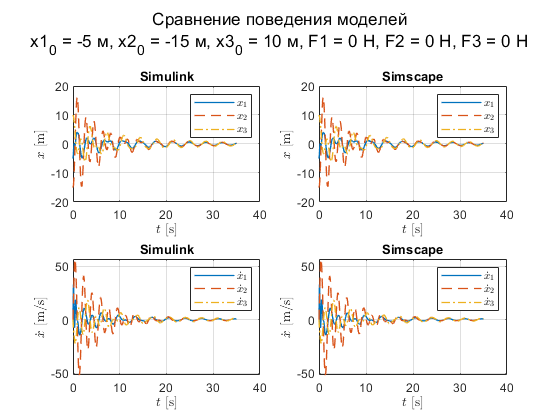


figure;
subplot(2,2,1)
plot(simu_1.simout.x1.time, simu_1.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_1.simout.x2.time, simu_1.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_1.simout.x3.time, simu_1.simout.x3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simulink');
subplot(2,2,3)
plot(simu_1.simout.dx1.time, simu_1.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_1.simout.dx2.time, simu_1.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_1.simout.dx3.time, simu_1.simout.dx3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_1.simout.x1.time, sims_1.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_1.simout.x2.time, sims_1.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
plot(sims_1.simout.x3.time, sims_1.simout.x3.data,...
    'linewidth',1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simscape');
subplot(2,2,4)
plot(sims_1.simout.dx1.time, sims_1.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_1.simout.dx2.time, sims_1.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_1.simout.dx3.time, sims_1.simout.dx3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(1)),' м, x2_0 = ', num2str(x2(1)),' м, '...
    'x3_0 = ', num2str(x3(1)),' м, '...
    'F1 = ', num2str(F_r(4)),' Н, F2 = ', num2str(F_r(4)),' Н, '...
    'F3 = ', num2str(F_r(4)),' Н']})

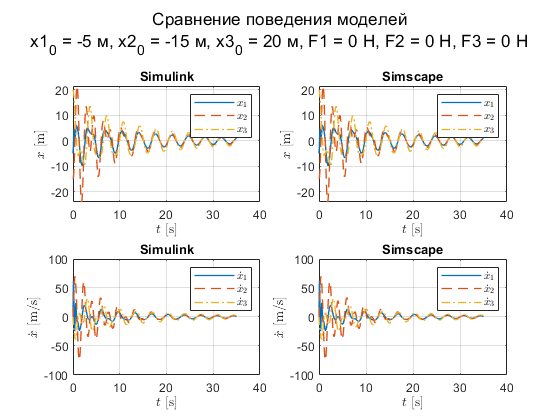



figure;
subplot(2,2,1)
plot(simu_2.simout.x1.time, simu_2.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_2.simout.x2.time, simu_2.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_2.simout.x3.time, simu_2.simout.x3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simulink');
subplot(2,2,3)
plot(simu_2.simout.dx1.time, simu_2.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_2.simout.dx2.time, simu_2.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_2.simout.dx3.time, simu_2.simout.dx3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_2.simout.x1.time, sims_2.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_2.simout.x2.time, sims_2.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
plot(sims_2.simout.x3.time, sims_2.simout.x3.data,...
    'linewidth',1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simscape');
subplot(2,2,4)
plot(sims_2.simout.dx1.time, sims_2.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_2.simout.dx2.time, sims_2.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_2.simout.dx3.time, sims_2.simout.dx3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(2)),' м, x2_0 = ', num2str(x2(2)),' м, '...
    'x3_0 = ', num2str(x3(2)),' м, '...
    'F1 = ', num2str(F_r(4)),' Н, F2 = ', num2str(F_r(4)),' Н, '...
    'F3 = ', num2str(F_r(4)),' Н']})

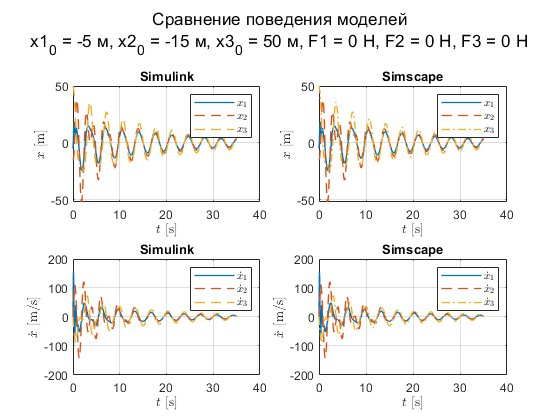



figure;
subplot(2,2,1)
plot(simu_3.simout.x1.time, simu_3.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_3.simout.x2.time, simu_3.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_3.simout.x3.time, simu_3.simout.x3.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simulink');
subplot(2,2,3)
plot(simu_3.simout.dx1.time, simu_3.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_3.simout.dx2.time, simu_3.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_3.simout.dx3.time, simu_3.simout.dx3.data,...
    'linewidth', 1, "LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_3.simout.x1.time, sims_3.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_3.simout.x2.time, sims_3.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
plot(sims_3.simout.x3.time, sims_3.simout.x3.data,...
    'linewidth',1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simscape');
subplot(2,2,4)
plot(sims_3.simout.dx1.time, sims_3.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_3.simout.dx2.time, sims_3.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_3.simout.dx3.time, sims_3.simout.dx3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(3)),' м, x2_0 = ', num2str(x2(3)),' м, '...
    'x3_0 = ', num2str(x3(3)),' м, '...
    'F1 = ', num2str(F_r(4)),' Н, F2 = ', num2str(F_r(4)),' Н, '...
    'F3 = ', num2str(F_r(4)),' Н']})

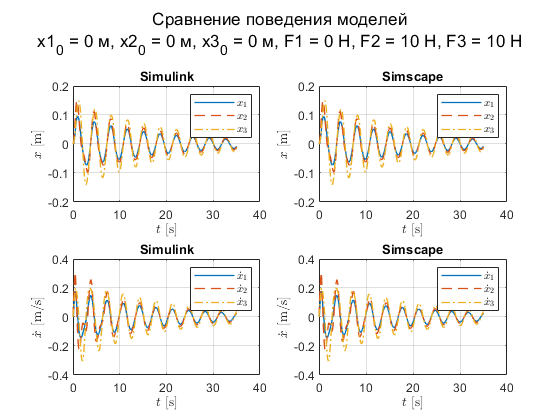



figure;
subplot(2,2,1)
plot(simu_F.simout.x1.time, simu_F.simout.x1.data,...
    'linewidth',1)
hold on
plot(simu_F.simout.x2.time, simu_F.simout.x2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_F.simout.x3.time, simu_F.simout.x3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simulink');
subplot(2,2,3)
plot(simu_F.simout.dx1.time, simu_F.simout.dx1.data,...
    'linewidth',1)
hold on
plot(simu_F.simout.dx2.time, simu_F.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(simu_F.simout.dx3.time, simu_F.simout.dx3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simulink');
subplot(2,2,2)
plot(sims_F.simout.x1.time, sims_F.simout.x1.data,...
    'linewidth',1)
hold on
plot(sims_F.simout.x2.time, sims_F.simout.x2.data,...
    'linewidth',1, "LineStyle","--")
plot(sims_F.simout.x3.time, sims_F.simout.x3.data,...
    'linewidth',1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$x$ [m]','interpreter','latex');
grid on;
legend('$x_1$','$x_2$','$x_3$','interpreter','latex');
title('Simscape');
subplot(2,2,4)
plot(sims_F.simout.dx1.time, sims_F.simout.dx1.data,...
    'linewidth',1)
hold on
plot(sims_F.simout.dx2.time, sims_F.simout.dx2.data,...
    'linewidth', 1, "LineStyle","--")
plot(sims_F.simout.dx3.time, sims_F.simout.dx3.data,...
    'linewidth', 1, "LineStyle","-.")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$\dot{x}$ [m/s]', 'interpreter','latex');
grid on;
legend('$\dot{x}_1$','$\dot{x}_2$','$\dot{x}_3$',...
    'interpreter','latex');
title('Simscape');
sgtitle({['Сравнение поведения моделей'];...
    ['x1_0 = ', num2str(x1(4)),' м, x2_0 = ', num2str(x2(4)),' м, '...
    'x3_0 = ', num2str(x3(4)),' м, '...
    'F1 = ', num2str(F_r(1)),' Н, F2 = ', num2str(F_r(2)),' Н, '...
    'F3 = ', num2str(F_r(3)),' Н']})